グラフ：Climb

[x,y] = meshgrid([200:5:300],[20000:1000:40000]);

%time, fuel共通変数値
weight = 69154.86794;
temp_difference = 9.633138618;
headwind = 3.41940696;
wingtip = 0.32001919;

%time最適化用係数
c_weight = 0.013924;
c_climbing_speed = 10.19;
c_cruise_altitude = 0.11099;
c_headwind = 4.456;
c_temp_difference = -45.829;
c_weight2temp_difference = 0.00053969;
c_climbing_speed2cruise_altitude = -0.00025713;
c_climbing_speed2headwind = -0.019362;
c_cruise_altitude2temp_difference = 0.00046103;
intercept_time = -4218.7;

%fuel最適化用係数
c_weight_f = 0.02711;
c_wingtip_f = -32.274;
c_climbing_speed_f = 5.1711;
c_cruise_altitude_f = 0.061158;
c_headwind_f = -1.2756;
c_temp_difference_f = -56.261;
c_weight2temp_difference_f = 0.00097275;
c_wingtip2headwind_f = 0.603;
intercept_fuel = -4102.5;

%TimeとFuelの同時最適化
mean_time = 973.9508197;
mean_fuel = 1267.725264;
weight_time = 1.0;
weight_fuel = 1.0;

%Time
time = intercept_time ...
    + c_weight .* weight ...
    + c_temp_difference .* temp_difference ...
    + c_climbing_speed .* x ...
    + c_cruise_altitude .* y ...
    + c_headwind .* headwind ...
    + c_weight2temp_difference * weight .* temp_difference ...
    + c_climbing_speed2cruise_altitude .* x .* y ...
    + c_climbing_speed2headwind .* x .* headwind ...
    + c_cruise_altitude2temp_difference .* y * temp_difference

time = 	1.0e+03 *

   -0.0176    0.0073    0.0322    0.0571    0.0820    0.1069    0.1318    0.1567    0.1816    0.2065    0.2314    0.2563    0.2812    0.3061    0.3310    0.3560    0.3809    0.4058    0.4307    0.4556    0.4805
    0.0464    0.0700    0.0936    0.1172    0.1409    0.1645    0.1881    0.2117    0.2353    0.2590    0.2826    0.3062    0.3298    0.3534    0.3771    0.4007    0.4243    0.4479    0.4715    0.4952    0.5188
    0.1104    0.1327    0.1550    0.1774    0.1997    0.2220    0.2444    0.2667    0.2891    0.3114    0.3337    0.3561    0.3784    0.4007    0.4231    0.4454    0.4677    0.4901    0.5124    0.5347    0.5571
    0.1744    0.1954    0.2165    0.2375    0.2586    0.2796    0.3007    0.3217    0.3428    0.3638    0.3849    0.4059    0.4270    0.4480    0.4691    0.4901    0.5112    0.5322    0.5533    0.5743    0.5954
    0.2384    0.2581    0.2779    0.2977    0.3174    0.3372    0.3570    0.3767    0.3965    0.4163    0.4360    0.4558    0.4755    0.4

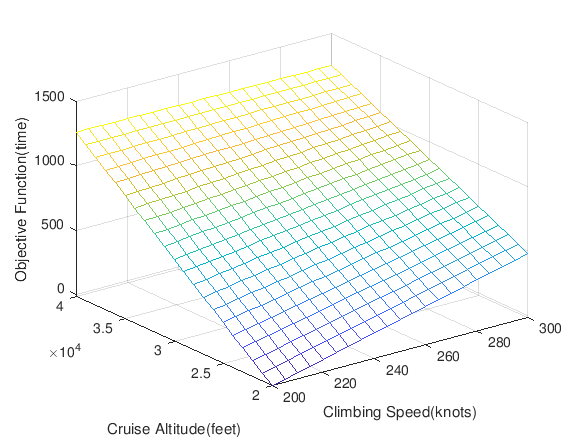

mesh(x,y,time)
xlabel('Climbing Speed(knots)')
ylabel('Cruise Altitude(feet)')
zlabel('Objective Function(time)')

fuel = intercept_fuel ...
    + c_weight_f .* weight ...
    + c_temp_difference_f .* temp_difference ...
    + c_climbing_speed_f .* x ...
    + c_cruise_altitude_f .* y ...
    + c_headwind_f .* headwind ...
    + c_wingtip_f .* wingtip ...
    + c_weight2temp_difference_f .* weight .* temp_difference ...
    + c_wingtip2headwind_f .* wingtip .* headwind

fuel = 	1.0e+03 *

    0.1217    0.1475    0.1734    0.1993    0.2251    0.2510    0.2768    0.3027    0.3285    0.3544    0.3802    0.4061    0.4320    0.4578    0.4837    0.5095    0.5354    0.5612    0.5871    0.6129    0.6388
    0.1829    0.2087    0.2346    0.2604    0.2863    0.3121    0.3380    0.3638    0.3897    0.4156    0.4414    0.4673    0.4931    0.5190    0.5448    0.5707    0.5965    0.6224    0.6483    0.6741    0.7000
    0.2440    0.2699    0.2957    0.3216    0.3474    0.3733    0.3991    0.4250    0.4509    0.4767    0.5026    0.5284    0.5543    0.5801    0.6060    0.6318    0.6577    0.6836    0.7094    0.7353    0.7611
    0.3052    0.3310    0.3569    0.3827    0.4086    0.4344    0.4603    0.4862    0.5120    0.5379    0.5637    0.5896    0.6154    0.6413    0.6671    0.6930    0.7189    0.7447    0.7706    0.7964    0.8223
    0.3663    0.3922    0.4180    0.4439    0.4697    0.4956    0.5215    0.5473    0.5732    0.5990    0.6249    0.6507    0.6766    0.7

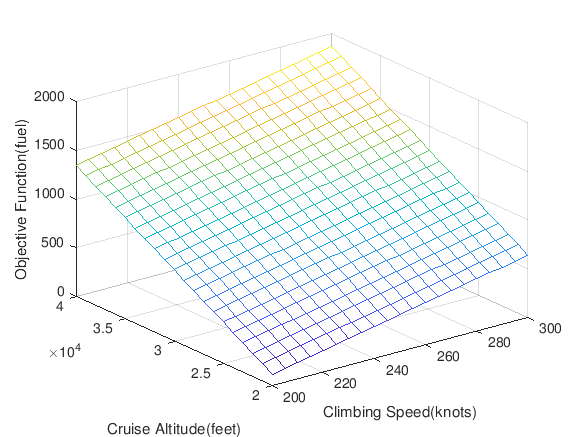

mesh(x,y,fuel)
xlabel('Climbing Speed(knots)')
ylabel('Cruise Altitude(feet)')
zlabel('Objective Function(fuel)')

time_fuel = weight_time .* time ./ mean_time + weight_fuel .* fuel ./ mean_fuel

time_fuel =     0.0779    0.1239    0.1698    0.2158    0.2618    0.3077    0.3537    0.3997    0.4456    0.4916    0.5376    0.5835    0.6295    0.6755    0.7214    0.7674    0.8134    0.8593    0.9053    0.9513    0.9972
    0.1918    0.2365    0.2811    0.3258    0.3704    0.4151    0.4597    0.5044    0.5490    0.5937    0.6383    0.6830    0.7276    0.7723    0.8169    0.8616    0.9062    0.9508    0.9955    1.0401    1.0848
    0.3058    0.3491    0.3925    0.4358    0.4791    0.5224    0.5658    0.6091    0.6524    0.6957    0.7391    0.7824    0.8257    0.8691    0.9124    0.9557    0.9990    1.0424    1.0857    1.1290    1.1723
    0.4198    0.4618    0.5038    0.5458    0.5878    0.6298    0.6718    0.7138    0.7558    0.7978    0.8398    0.8818    0.9238    0.9659    1.0079    1.0499    1.0919    1.1339    1.1759    1.2179    1.2599
    0.5337    0.5744    0.6151    0.6558    0.6965    0.7372    0.7778    0.8185    0.8592    0.8999    0.9406    0.9813    1.0220    1.0627    

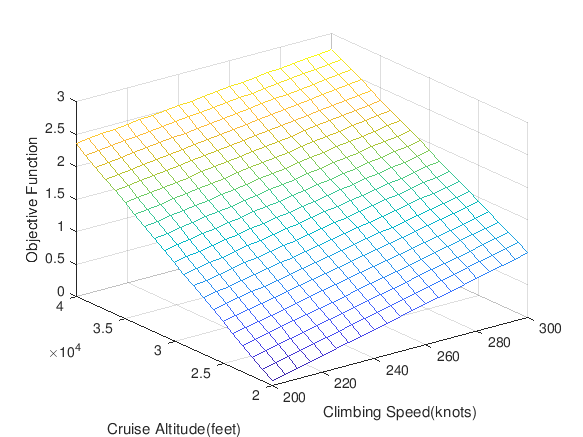

mesh(x,y,time_fuel)
xlabel('Climbing Speed(knots)')
ylabel('Cruise Altitude(feet)')
zlabel('Objective Function')